# 参数

clear,clc
%全交换面积计算参数
Lr = 4.1;%辐射管长度
Ws = 3.6;%钢板宽
Wfur = 4.6;%炉宽
epsilon_r = 0.5;%黑度
rho_r = 0.5;%反射率
epsilon_w = 0.85;
rho_w = 0.15;
epsilon_s = 0.75;
rho_s = 0.25;
%序号 直径 段长 h1 h2 辐射管间隔数组 功率数组
cellZoneInfo = {1,0.3,8.7,0.65,0.91,[2700 600 600 600 600 600 1200 600 1200],[115 150 115 150 115 150 115 150 115/2];
         2,0.3,7.2,0.65,0.91,[600 600 600 600 600 600 600 600 600 600 600 600],[115/2 150 115 150 115 150 115 150 115 150 115 150 95/2];
         3,0.28,7.2,0.66,0.92,[600 600 600 600 600 600 1200 600 1200 600],[95/2 120 95 120 95 120 95 120 95 120 95/2];
         4,0.28,7.2,0.66,0.92,[600 2400 600 600 1200 600 600 600],[95/2 120 95 120 95 120 95 120 95/2];
         5,0.28,7.2,0.66,0.92,[600 1200 600 1200 600 1200 600 1200],[95/2 120 95 120 95 120 95 120 95/2];
         6,0.28,7.2,0.66,0.92,[1200 1200 1200 1200 1200 1200],[95/2 120 95 120 95 120 95/2];
         7,0.28,6.6,0.66,0.92,[1200 2400 1800 1200],[95/2 120 95 120 95/2];
         8,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[95/2 80 55 80 55/2];
         9,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[55/2 80 55 80 55/2];
         10,0.208,7.2,0.696,0.956,[1800 1800 1800 1800],[55/2 80 55 80 55/2];
         11,0.208,9.3,0.696,0.956,[1800 1800 1800 1800 2100],[55/2 80 55 120 95];}

cellZoneInfo = 11×7 cell 数组
    {[ 1]}    {[0.3000]}    {[8.7000]}    {[0.6500]}    {[0.9100]}    {[         2700 600 600 600 600 600 1200 600 1200]}    {[                    115 150 115 150 115 150 115 150 57.5000]}
    {[ 2]}    {[0.3000]}    {[7.2000]}    {[0.6500]}    {[0.9100]}    {[600 600 600 600 600 600 600 600 600 600 600 600]}    {[57.5000 150 115 150 115 150 115 150 115 150 115 150 47.5000]}
    {[ 3]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[      600 600 600 600 600 600 1200 600 1200 600]}    {[            47.5000 120 95 120 95 120 95 120 95 120 47.5000]}
    {[ 4]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[              600 2400 600 600 1200 600 600 600]}    {[                   47.5000 120 95 120 95 120 95 120 47.5000]}
    {[ 5]}    {[0.2800]}    {[7.2000]}    {[0.6600]}    {[0.9200]}    {[            600 1200 600 1200 600 1200 600 1200]}    {[                   47.5000 120 95 120 95 120 95 120 47.5000]}
    {[ 6]}    {[0.2800]}   


%三元法计算参数
%初(xia)始(gei)化区域温度场
Tw_init = [700 720 740 760 780 800 820 840 860 870 870] + 273.15 ;
Ts_1_init = [150 250 420 555 666 777 820 835 850 870 870] + 273.15;
% Ts_1_init = [350 550 620 755 866 977 1020 1035 1050 1070 1070] + 273.15;

Lfur = 82.2;%炉长,m
ths = 50/1000;%板厚,m
Time_heat = 80 * 60;%加热时间,s
Vs = Lfur / Time_heat;%物料速度
Thw = 0.3;%炉墙厚度
lambda_w = 0.138*250/300+0.15*50/300;%炉墙导热系数
hw = 15;%炉墙自然对流换热系数
Temp_out = 30+273.15;%环境温度,k
density_s = 7860;
sigma = 5.67*10^(-8);%斯忒藩-玻尔兹曼常数
N = 10;%层数
s_timeStep = 1000;%时间步长节点数


# 全交换面积calc  1.1ver

- **1.0 ver:**单区域计算基本代码

- **1.1 ver:**循环计算多区域

**Todo:**辐射管黑度影响研究，完整性修正系数研究 

SR = zeros(1,length(cellZoneInfo));
SW = zeros(1,length(cellZoneInfo));
WR = zeros(1,length(cellZoneInfo));


for i = 1:length(cellZoneInfo)

    %计算
    S = cellZoneInfo{i,6}./1000;%辐射管间隔数组
    d = cellZoneInfo{i,2};%辐射管直径
    L = cellZoneInfo{i,3};%段长
    h1 = cellZoneInfo{i,4};%见函数
    h2 = cellZoneInfo{i,5};
    kr = Lr/Wfur;%辐射管长度系数
    ks = Ws/Wfur;%钢板宽度系数

    xrp = zeros(1,length(S));
    for j = 1:length(S)
        if S(j) == 2.7 || S(j) == 2.1
            xrp(j) = (d/2)/S(j)*atan(S(j)/(d/2));
        else
            xrp(j) = S(j)/(pi*d)*(1+d/S(j)*acos(d/S(j))-(1-(d/S(j))^2)^(1/2));
        end
    end
    %加权辐射管对假想面角系数
    Xrp = 0;
    for j = 1:length(xrp)
        Xrp = Xrp+S(j)/L*xrp(j);
    end
    %角系数

    Xp1w2 = phi_p1_w2(Wfur,L,h1) + phi_p2_w1(Wfur,L,h1);
    Xp2s = phi_p2_s(Wfur,L,h2);
    Xp2w1 = phi_p2_w1(Wfur,L,h2);
    
    % 论文中修正的角系数
    % Xrs = Xrp * 1/kr * Xp2s * ks;%计算Xrs
    Xrw = Xrp * 1/kr *Xp1w2 + Xrp * 1/kr *Xp2w1;
    Xrr = 1 - 2 * Xrp;%计算Xrr
    % Xrr = 1 - Xrw - Xrs;%完整性计算Xrr
    Xrs = 1 - Xrw - Xrr;%完整性计算Xrs
    
    %不修正的角系数
    % Xrs = Xrp * Xp2s ;
    % Xrw = Xrp *Xp1w2 + Xrp *Xp2w1;
    % Xrr = 1 - 2 * Xrp;

    Fs = L*Ws;
    Fw = L*Wfur+L*h1*2+L*h2*2;
    Fr = pi*d*length(S)*Lr;

    Xss= 0;
    Xsr = Xrs * Fr/Fs;
    Xsw = 1 - Xsr - Xss;
    Xwr = Xrw * Fr/Fw;
    Xws = Xsw * Fs/Fw;
    Xww = 1 - Xwr - Xws;
    %直接交换面积
    rr = Fr * Xrr;
    rw = Fr * Xrw;
    rs = Fr * Xrs;
    wr = Fw * Xwr;
    ww = Fw * Xww;
    ws = Fw * Xws;
    sr = Fs * Xsr;
    sw = Fs * Xsw;
    ss = Fs * Xss;

    %全交换面积

    SR(i) = calculate_SR(Fr, Fw, Fs, epsilon_r, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xsr, Xww, Xwr);
    SW(i) = calculate_SW(Fr, Fw, Fs, epsilon_w, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xwr, Xsr, Xww);
    WR(i) = calculate_WR(Fr, Fw, Fs, epsilon_r, epsilon_w, rho_r, rho_w, rho_s, Xrr, Xwr, Xsr, Xsw, Xww);
    
end
% SR = SR + 100;
% SW = SW + 100;
% WR = WR + 100;

RS = SR

RS =     4.5115    7.0134    5.6168    4.5826    4.5835    3.5048    2.3996    1.7822    1.7822    1.7822    1.9301


WS = SW

WS =    17.3465   10.4000   11.9667   13.1323   13.1309   14.3494   14.0650   16.3139   16.3139   16.3139   21.5975


RW = WR

RW =     8.7697   12.8364   10.3866    8.5359    8.5374    6.5778    4.4526    3.3940    3.3940    3.3940    3.8616


SR

SR =     4.5115    7.0134    5.6168    4.5826    4.5835    3.5048    2.3996    1.7822    1.7822    1.7822    1.9301


SW

SW =    17.3465   10.4000   11.9667   13.1323   13.1309   14.3494   14.0650   16.3139   16.3139   16.3139   21.5975


WR

WR =     8.7697   12.8364   10.3866    8.5359    8.5374    6.5778    4.4526    3.3940    3.3940    3.3940    3.8616


# 三元法calc   1.1ver

- **1.0 ver**:常物性计算基本代码

- **1.1 ver**:钢坯变物性计算追加

- **1.2 ver**:炉围常物性一维差分追加，施工中：

**Todo:**已确定炉围初始温度场对出炉钢温有较大影响，黑度增加对炉围钢温无影响疑似与无炉围一维差分计算有关，现停止更改无炉围一维差分修正温度的版本，上传分支并增加炉围一维计算。

%初始化
Tw_zone = zeros(1,length(cellZoneInfo));
Tr_zone = zeros(1,length(cellZoneInfo));
Ts_zone = zeros(1,length(cellZoneInfo));

phi_r = zeros(1,length(cellZoneInfo));

Temp_inlet = zeros(N+1,length(cellZoneInfo));
Temp_inlet(:,1) = 30 + 273.15;
Temp_total = zeros(length(cellZoneInfo),s_timeStep*length(cellZoneInfo));

for i = 1:length(cellZoneInfo)

    phi_r(i) = sum(cellZoneInfo{i,7})*1000;%W
    Ts_1 = Ts_1_init(i);%段内物料表面初始温度
    Ts_2 = 0;%初始化，进循环用
    L = cellZoneInfo{i,3};%段长
    Time_zone = L / Vs;%段内时间

    Tw_1 = Tw_init(i);
    Tw_2 = 0;%初始化，进循环
    
    
    while(abs((Ts_2 - Ts_1)/Ts_1)>=0.001)

        Ts_1 = Ts_2;%迭代

        %能量平衡解Tr
        syms Tr;
        f1 = sigma*RW(i)*(Tr^4 - Tw_1^4) + sigma*RS(i)*(Tr^4 - Ts_1^4) == phi_r(i);
        Tr = solve(f1,Tr);
        Tr = vpa(Tr);
        Tr= Tr(imag(Tr) == 0 & real(Tr) > 0);

    %能量平衡解Tw   
        syms Tw_1;
        f2 = sigma*SW(i)*(Ts_1^4 - Tw_1^4) + sigma*RW(i)*(Tr^4 - Tw_1^4) == Fw*(Tw_1 - Temp_out)/(1/hw+Thw/lambda_w);
        Tw_1 = solve(f2,Tw_1);
        Tw_1 = vpa(Tw_1);
        Tw_1= Tw_1(imag(Tw_1) == 0 & real(Tw_1) > 0);

    
    %差分求炉围温度
    


    %求钢坯表面热流    
        qcon_s = -(sigma*RS(i)*(Ts_1^4 - Tr^4) + sigma*WS(i)*(Ts_1^4 - Tw_1^4))/Fs;%钢坯表面热流密度

    %差分求物料温度   
        T = Temp_inlet(:,i);
        delta_t = Time_zone / s_timeStep;%时间步长
        delta_x = ths/(2*N);%空间步长
        Temp_zone = zeros(length(cellZoneInfo),s_timeStep);
        for j = 1:s_timeStep
            T = TDMA(qcon_s,N,density_s,delta_t,delta_x,T);
            Temp_zone(:,j) = T;
        end
    
        Ts_2 = sum(Temp_zone(1,:))/s_timeStep;%热流反算物料表面温度
    
        % if abs((Ts_2 - Ts_1)/Ts_1)<=0.001
        %     break;
        % end
    end
    
    % sprintf('%.3e', phi_r(i)/sigma)
    % sprintf('%.3e', RW(i)*Tw^4)
    % sprintf('%.3e', RS(i)*Ts_2^4)

    Temp_inlet(:,i+1) = T
    Tw_zone(i) = Tw_1 ;%K
    Tr_zone(i) = Tr ;%K
    Ts_zone(i) = Ts_2 ;%K
    Temp_total(:,1+(i-1)*s_timeStep:i*s_timeStep) = Temp_zone;%K

end

Temp_inlet =   303.1500  475.0287         0         0         0         0         0         0         0         0         0
  303.1500  473.1688         0         0         0         0         0         0         0         0         0
  303.1500  471.5095         0         0         0         0         0         0         0         0         0
  303.1500  470.0492         0         0         0         0         0         0         0         0         0
  303.1500  468.7865         0         0         0         0         0         0         0         0         0
  303.1500  467.7201         0         0         0         0         0         0         0         0         0
  303.1500  466.8489         0         0         0         0         0         0         0         0         0
  303.1500  466.1722         0         0         0         0         0         0         0         0         0
  303.1500  465.6893         0         0         0         0         0         0         0         

Temp_inlet =   303.1500  475.0287  658.1394         0         0         0         0         0         0         0         0
  303.1500  473.1688  655.0395         0         0         0         0         0         0         0         0
  303.1500  471.5095  652.2794         0         0         0         0         0         0         0         0
  303.1500  470.0492  649.8545         0         0         0         0         0         0         0         0
  303.1500  468.7865  647.7608         0         0         0         0         0         0         0         0
  303.1500  467.7201  645.9948         0         0         0         0         0         0         0         0
  303.1500  466.8489  644.5538         0         0         0         0         0         0         0         0
  303.1500  466.1722  643.4354         0         0         0         0         0         0         0         0
  303.1500  465.6893  642.6379         0         0         0         0         0         0         

Temp_inlet =   303.1500  475.0287  658.1394  764.9299         0         0         0         0         0         0         0
  303.1500  473.1688  655.0395  762.5838         0         0         0         0         0         0         0
  303.1500  471.5095  652.2794  760.4983         0         0         0         0         0         0         0
  303.1500  470.0492  649.8545  758.6687         0         0         0         0         0         0         0
  303.1500  468.7865  647.7608  757.0910         0         0         0         0         0         0         0
  303.1500  467.7201  645.9948  755.7617         0         0         0         0         0         0         0
  303.1500  466.8489  644.5538  754.6779         0         0         0         0         0         0         0
  303.1500  466.1722  643.4354  753.8373         0         0         0         0         0         0         0
  303.1500  465.6893  642.6379  753.2381         0         0         0         0         0         

Temp_inlet =   303.1500  475.0287  658.1394  764.9299  842.5537         0         0         0         0         0         0
  303.1500  473.1688  655.0395  762.5838  840.5212         0         0         0         0         0         0
  303.1500  471.5095  652.2794  760.4983  838.7084         0         0         0         0         0         0
  303.1500  470.0492  649.8545  758.6687  837.1134         0         0         0         0         0         0
  303.1500  468.7865  647.7608  757.0910  835.7344         0         0         0         0         0         0
  303.1500  467.7201  645.9948  755.7617  834.5700         0         0         0         0         0         0
  303.1500  466.8489  644.5538  754.6779  833.6190         0         0         0         0         0         0
  303.1500  466.1722  643.4354  753.8373  832.8803         0         0         0         0         0         0
  303.1500  465.6893  642.6379  753.2381  832.3533         0         0         0         0         

Temp_inlet =   303.1500  475.0287  658.1394  764.9299  842.5537  918.2922         0         0         0         0         0
  303.1500  473.1688  655.0395  762.5838  840.5212  916.1611         0         0         0         0         0
  303.1500  471.5095  652.2794  760.4983  838.7084  914.2536         0         0         0         0         0
  303.1500  470.0492  649.8545  758.6687  837.1134  912.5699         0         0         0         0         0
  303.1500  468.7865  647.7608  757.0910  835.7344  911.1103         0         0         0         0         0
  303.1500  467.7201  645.9948  755.7617  834.5700  909.8750         0         0         0         0         0
  303.1500  466.8489  644.5538  754.6779  833.6190  908.8640         0         0         0         0         0
  303.1500  466.1722  643.4354  753.8373  832.8803  908.0776         0         0         0         0         0
  303.1500  465.6893  642.6379  753.2381  832.3533  907.5158         0         0         0         

Temp_inlet =   303.1500  475.0287  658.1394  764.9299  842.5537  918.2922  971.5311         0         0         0         0
  303.1500  473.1688  655.0395  762.5838  840.5212  916.1611  969.9680         0         0         0         0
  303.1500  471.5095  652.2794  760.4983  838.7084  914.2536  968.5691         0         0         0         0
  303.1500  470.0492  649.8545  758.6687  837.1134  912.5699  967.3345         0         0         0         0
  303.1500  468.7865  647.7608  757.0910  835.7344  911.1103  966.2642         0         0         0         0
  303.1500  467.7201  645.9948  755.7617  834.5700  909.8750  965.3585         0         0         0         0
  303.1500  466.8489  644.5538  754.6779  833.6190  908.8640  964.6172         0         0         0         0
  303.1500  466.1722  643.4354  753.8373  832.8803  908.0776  964.0407         0         0         0         0
  303.1500  465.6893  642.6379  753.2381  832.3533  907.5158  963.6288         0         0         

Temp_inlet = 1.0e+03 *

    0.3031    0.4750    0.6581    0.7649    0.8426    0.9183    0.9715    1.0027         0         0         0
    0.3031    0.4732    0.6550    0.7626    0.8405    0.9162    0.9700    1.0017         0         0         0
    0.3031    0.4715    0.6523    0.7605    0.8387    0.9143    0.9686    1.0008         0         0         0
    0.3031    0.4700    0.6499    0.7587    0.8371    0.9126    0.9673    1.0000         0         0         0
    0.3031    0.4688    0.6478    0.7571    0.8357    0.9111    0.9663    0.9993         0         0         0
    0.3031    0.4677    0.6460    0.7558    0.8346    0.9099    0.9654    0.9987         0         0         0
    0.3031    0.4668    0.6446    0.7547    0.8336    0.9089    0.9646    0.9982         0         0         0
    0.3031    0.4662    0.6434    0.7538    0.8329    0.9081    0.9640    0.9978         0         0         0
    0.3031    0.4657    0.6426    0.7532    0.8324    0.9075    0.9636    0.9975        

Temp_inlet = 1.0e+03 *

    0.3031    0.4750    0.6581    0.7649    0.8426    0.9183    0.9715    1.0027    1.0249         0         0
    0.3031    0.4732    0.6550    0.7626    0.8405    0.9162    0.9700    1.0017    1.0243         0         0
    0.3031    0.4715    0.6523    0.7605    0.8387    0.9143    0.9686    1.0008    1.0237         0         0
    0.3031    0.4700    0.6499    0.7587    0.8371    0.9126    0.9673    1.0000    1.0232         0         0
    0.3031    0.4688    0.6478    0.7571    0.8357    0.9111    0.9663    0.9993    1.0227         0         0
    0.3031    0.4677    0.6460    0.7558    0.8346    0.9099    0.9654    0.9987    1.0223         0         0
    0.3031    0.4668    0.6446    0.7547    0.8336    0.9089    0.9646    0.9982    1.0220         0         0
    0.3031    0.4662    0.6434    0.7538    0.8329    0.9081    0.9640    0.9978    1.0218         0         0
    0.3031    0.4657    0.6426    0.7532    0.8324    0.9075    0.9636    0.9975    1.02

Temp_inlet = 1.0e+03 *

    0.3031    0.4750    0.6581    0.7649    0.8426    0.9183    0.9715    1.0027    1.0249    1.0463         0
    0.3031    0.4732    0.6550    0.7626    0.8405    0.9162    0.9700    1.0017    1.0243    1.0457         0
    0.3031    0.4715    0.6523    0.7605    0.8387    0.9143    0.9686    1.0008    1.0237    1.0452         0
    0.3031    0.4700    0.6499    0.7587    0.8371    0.9126    0.9673    1.0000    1.0232    1.0447         0
    0.3031    0.4688    0.6478    0.7571    0.8357    0.9111    0.9663    0.9993    1.0227    1.0443         0
    0.3031    0.4677    0.6460    0.7558    0.8346    0.9099    0.9654    0.9987    1.0223    1.0439         0
    0.3031    0.4668    0.6446    0.7547    0.8336    0.9089    0.9646    0.9982    1.0220    1.0437         0
    0.3031    0.4662    0.6434    0.7538    0.8329    0.9081    0.9640    0.9978    1.0218    1.0434         0
    0.3031    0.4657    0.6426    0.7532    0.8324    0.9075    0.9636    0.9975    1.02

Temp_inlet = 1.0e+03 *

    0.3031    0.4750    0.6581    0.7649    0.8426    0.9183    0.9715    1.0027    1.0249    1.0463    1.0677
    0.3031    0.4732    0.6550    0.7626    0.8405    0.9162    0.9700    1.0017    1.0243    1.0457    1.0671
    0.3031    0.4715    0.6523    0.7605    0.8387    0.9143    0.9686    1.0008    1.0237    1.0452    1.0666
    0.3031    0.4700    0.6499    0.7587    0.8371    0.9126    0.9673    1.0000    1.0232    1.0447    1.0661
    0.3031    0.4688    0.6478    0.7571    0.8357    0.9111    0.9663    0.9993    1.0227    1.0443    1.0657
    0.3031    0.4677    0.6460    0.7558    0.8346    0.9099    0.9654    0.9987    1.0223    1.0439    1.0654
    0.3031    0.4668    0.6446    0.7547    0.8336    0.9089    0.9646    0.9982    1.0220    1.0437    1.0651
    0.3031    0.4662    0.6434    0.7538    0.8329    0.9081    0.9640    0.9978    1.0218    1.0434    1.0649
    0.3031    0.4657    0.6426    0.7532    0.8324    0.9075    0.9636    0.9975    1.02

Temp_inlet = 1.0e+03 *

    0.3031    0.4750    0.6581    0.7649    0.8426    0.9183    0.9715    1.0027    1.0249    1.0463    1.0677    1.1097
    0.3031    0.4732    0.6550    0.7626    0.8405    0.9162    0.9700    1.0017    1.0243    1.0457    1.0671    1.1088
    0.3031    0.4715    0.6523    0.7605    0.8387    0.9143    0.9686    1.0008    1.0237    1.0452    1.0666    1.1080
    0.3031    0.4700    0.6499    0.7587    0.8371    0.9126    0.9673    1.0000    1.0232    1.0447    1.0661    1.1073
    0.3031    0.4688    0.6478    0.7571    0.8357    0.9111    0.9663    0.9993    1.0227    1.0443    1.0657    1.1067
    0.3031    0.4677    0.6460    0.7558    0.8346    0.9099    0.9654    0.9987    1.0223    1.0439    1.0654    1.1062
    0.3031    0.4668    0.6446    0.7547    0.8336    0.9089    0.9646    0.9982    1.0220    1.0437    1.0651    1.1058
    0.3031    0.4662    0.6434    0.7538    0.8329    0.9081    0.9640    0.9978    1.0218    1.0434    1.0649    1.1055
    0.30

Tw_zone - 273.15%各段温度

ans =   623.8830  790.1391  729.7584  726.2339  768.2839  774.5779  779.3399  777.2635  794.5302  814.0001  848.0553


Tr_zone - 273.15

ans = 1.0e+03 *

    0.9041    0.9534    0.9045    0.9071    0.9325    0.9403    0.9467    0.9346    0.9369    0.9499    1.0050


Ts_zone - 273.15

ans =   119.6073  296.4503  437.6743  530.2170  607.4650  670.8455  713.0568  740.0747  762.3951  783.8527  816.0348


Temp_zone(1,s_timeStep) - 273.15 %物料出炉温度

ans = 836.5009

Temp_total = Temp_total -273.15%钢温温度场

Temp_total =    33.4035   32.5963   33.9497   33.9635   34.6429   34.8867   35.3263   35.6179   35.9606   36.2482   36.5440   36.8155   37.0834   37.3383   37.5870   37.8271   38.0613   38.2892   38.5120   38.7298   38.9433   39.1528   39.3587   39.5614   39.7611   39.9581   40.1527   40.3451   40.5354   40.7239   40.9108   41.0962   41.2801   41.4629   41.6444   41.8250   42.0046   42.1833   42.3613   42.5386   42.7152   42.8912   43.0667   43.2417   43.4162   43.5904   43.7641   43.9376   44.1107   44.2835
   31.3022   31.5741   32.2575   32.6038   33.0648   33.4063   33.7714   34.0882   34.4030   34.6944   34.9777   35.2471   35.5082   35.7596   36.0038   36.2407   36.4715   36.6965   36.9166   37.1320   37.3432   37.5507   37.7547   37.9557   38.1538   38.3494   38.5426   38.7338   38.9230   39.1105   39.2963   39.4808   39.6639   39.8459   40.0267   40.2066   40.3855   40.5637   40.7411   40.9178   41.0939   41.2695   41.4445   41.6191   41.7932   41.9670   42.1404   42.3135   42.

# 绘图      1.1ver

- **1.0 ver:**第一层和最后一层的升温曲线 + 三元各区域温度曲线

- **1.1 ver:**各层升温曲线

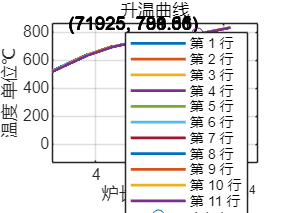

%物料第一层和中间层(最后一层)升温曲线
% % 获取所有处理区间的长度，并将其转换为 x 坐标区间长度
% process_vector = [cellZoneInfo{:,3}] * 1000;
% 
% % 初始化 x 坐标和 y 坐标
% x_total = [];
% y1_total = [];
% y11_total = [];
% 
% % 累积和计算 x 坐标
% x_start = 0;
% for i = 1:length(cellZoneInfo)
%     % 计算当前区间的 x 坐标
%     x_end = x_start + process_vector(i);
%     x = linspace(x_start, x_end, s_timeStep);
%     x_total = [x_total, x];
% 
%     % 创建当前区间的矩阵 
%     matrix = Temp_total(:, 1 + (i-1) * s_timeStep : i * s_timeStep);
% 
%     % 提取第一行和最后一行
%     y1 = matrix(1, :);
%     y11 = matrix(11, :);
% 
%     % 累积 y 坐标
%     y1_total = [y1_total, y1];
%     y11_total = [y11_total, y11];
% 
%     % 更新 x 起点
%     x_start = x_end;
% end
% 
% % 绘制折线图
% figure;
% plot(x_total, y1_total, 'r-', 'LineWidth', 1.5); 
% hold on;
% plot(x_total, y11_total, 'b-', 'LineWidth', 1.5);
% hold on;
% 
% % 添加图例和标签
% legend('表面温度', '中心温度');
% xlabel('炉长 单位:mm');
% ylabel('温度 单位℃');
% title('升温曲线');
% 
% % 显示网格
% grid on;
% 
% % 查找 x = 71925 对应的 y 值
% x_target = 71925;
% [~, idx] = min(abs(x_total - x_target)); % 找到最接近 x_target 的索引
% y1_target = y1_total(idx);
% y11_target = y11_total(idx);
% 
% % 在图中标注 x = 71925 时对应的 y 值
% plot(x_target, y1_target, 'ro'); % 在表面温度曲线上的标注
% text(x_target, y1_target, sprintf('(%d, %.2f)', x_target, y1_target), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
% 
% plot(x_target, y11_target, 'bo'); % 在中心温度曲线上的标注
% text(x_target, y11_target, sprintf('(%d, %.2f)', x_target, y11_target), 'VerticalAlignment', 'top', 'HorizontalAlignment', 'left');
% 
% hold off;



%各层升温曲线
% 获取所有处理区间的长度，并将其转换为 x 坐标区间长度
process_vector = [cellZoneInfo{:,3}] * 1000;

% 初始化 x 坐标和 y 坐标
x_total = [];

% 累积和计算 x 坐标
x_start = 0;
for i = 1:length(cellZoneInfo)
    % 计算当前区间的 x 坐标
    x_end = x_start + process_vector(i);
    x = linspace(x_start, x_end, s_timeStep);
    x_total = [x_total, x];
    x_start = x_end;
end

% 绘制折线图
figure;

% 定义颜色列表
colors = lines(11); % 使用 lines 函数生成颜色

% 绘制每一行的数据
for row = 1:size(Temp_total, 1)
    % 提取当前行的所有区间数据
    y_total = [];
    for i = 1:length(cellZoneInfo)
        % 创建当前区间的矩阵 
        matrix = Temp_total(:, 1 + (i-1) * s_timeStep : i * s_timeStep);
        % 提取当前行数据
        y = matrix(row, :);
        y_total = [y_total, y];
    end
    % 绘制当前行的折线图
    plot(x_total, y_total, 'Color', colors(row, :), 'LineWidth', 1.5);
    hold on;
end

% 添加图例和标签
legend(arrayfun(@(x) sprintf('第 %d 层', x), 1:11, 'UniformOutput', false));
xlabel('炉长 单位:mm');
ylabel('温度 单位℃');
title('升温曲线');

% 显示网格
grid on;

% 查找 x = 71925 对应的 y 值
x_target = 71925;
[~, idx] = min(abs(x_total - x_target)); % 找到最接近 x_target 的索引

% 在图中标注 x = 71925 时对应的 y 值
for row = 1:size(Temp_total, 1)
    % 提取当前行的所有区间数据
    y_total = [];
    for i = 1:length(cellZoneInfo)
        % 创建当前区间的矩阵 
        matrix = Temp_total(:, 1 + (i-1) * s_timeStep : i * s_timeStep);
        % 提取当前行数据
        y = matrix(row, :);
        y_total = [y_total, y];
    end
    % 获取对应索引处的 y 坐标值
    y_target = y_total(idx);
    % 在折线图上标注
    plot(x_target, y_target, 'o', 'Color', colors(row, :)); 
    text(x_target, y_target, sprintf('(%d, %.2f)', x_target, y_target), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

hold off;

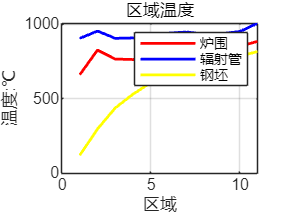





%三元各区域升温曲线
x = linspace(1,11,11);
yTw = Tw_zone - 237.15;
yTr = Tr_zone - 273.15;
yTs = Ts_zone - 273.15;

% 绘制折线图
figure;
plot(x, yTw, 'r-', 'LineWidth', 1.5);
hold on;
plot(x, yTr, 'b-', 'LineWidth', 1.5); 
hold on;
plot(x, yTs, 'y-', 'LineWidth', 1.5); 


% 添加图例和标签
legend('炉围', '辐射管', '钢坯');
xlabel('区域');
ylabel('温度:℃');
title('区域温度');

% 显示网格
grid on;
hold off;

**函数**

%计算空间角系数
%x为炉宽，m;h为炉高，m;y为炉段长度，m;h1为辐射管上端距炉墙高度，m;h2为辐射管下端距假象面p高度，m
function phi = phi_p1_w2(x, y, h1)
    X = x / h1;
    Y = y / h1;
    
    term1 = sqrt((1 + X^2) * (1 + Y^2)) / (1 + X^2 + Y^2);
    term2 = X * sqrt(1 + Y^2) * atan(X / sqrt(1 + Y^2));
    term3 = Y * sqrt(1 + X^2) * atan(Y / sqrt(1 + X^2));
    term4 = X * atan(X) + Y * atan(Y);
    
    phi = (2 / (pi * X * Y)) * (log(term1) + term2 + term3 - term4);
end

function phi = phi_p2_s(x, y, h2)
    X = x / h2;
    Y = y / h2;
    
    term1 = sqrt((1 + X^2) * (1 + Y^2)) / (1 + X^2 + Y^2);
    term2 = X * sqrt(1 + Y^2) * atan(X / sqrt(1 + Y^2));
    term3 = Y * sqrt(1 + X^2) * atan(Y / sqrt(1 + X^2));
    term4 = X * atan(X) + Y * atan(Y);
    
    phi = (2 / (pi * X * Y)) * (log(term1) + term2 + term3 - term4);
end

function phi = phi_p2_w1(x, y, h2)
    H = h2 / y;
    W = x / y;
    
    term1 = W * atan(1 / W) + H * atan(1 / H);
    term2 = sqrt(H^2 + W^2) * atan(1 / sqrt(H^2 + W^2));
    term3 = (1 + W^2) * (1 + H^2) / (1 + W^2 + H^2) * (W^2 * (1 + W^2 + H^2) / ((1 + W^2) * (W^2 + H^2)))^(W^2);
    term4 = (H^2 * (1 + H^2 + W^2) / ((1 + H^2) * (H^2 + W^2)))^(H^2);
    phi = (2 / (pi * W)) * (term1 - term2 + 1/4*log(term3 * term4));
end

function phi = phi_p2_w11(x, y, h2)
    % 定义H和W
    H = h2 / y;
    W = x / y;
    
    % 计算第一部分
    part1 = W * atan(1 / W) + H * atan(1 / H);
    
    % 计算第二部分
    part2 = sqrt(H^2 + W^2) * atan(1 / sqrt(H^2 + W^2));
    
    % 计算第三部分中的内部分数
    term1_numerator = (1 + W^2) * (1 + H^2);
    term1_denominator = 1 + W^2 + H^2;
    term1 = term1_numerator / term1_denominator;
    
    term2_numerator = W^2 * (1 + W^2 + H^2);
    term2_denominator = (1 + W^2) * (W^2 + H^2);
    term2 = term2_numerator / term2_denominator;
    term2 = term2^(W^2);
    
    term3_numerator = H^2 * (1 + H^2 + W^2);
    term3_denominator = (1 + H^2) * (H^2 + W^2);
    term3 = term3_numerator / term3_denominator;
    term3 = term3^(H^2);
    
    % 计算第三部分
    part3 = (1/4) * log(term1 * term2 * term3);
    
    % 计算最终结果
    phi = (2 / (pi * W)) * (part1 - part2 + part3);
    
end

%全交换面积计算

function SR = calculate_SR(Fr, Fw, Fs, epsilon_r, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xsr, Xww, Xwr)
    % 计算 SR
    numerator = -Fr * epsilon_r * Fs * epsilon_s * (-Fw * rho_w * Xwr * Xws + Fs * Xsr * (-1 + rho_w * Xww));
    denominator = Fr * (-1 + rho_r * Xrr) * (Fw * rho_s * rho_w * Xws^2 + Fs * (-1 + rho_w * Xww)) ...
                  + Fs * rho_r * (-Fw * rho_w * Xwr * (Xwr + 2 * rho_s * Xsr * Xws) + Fs * rho_s * Xsr^2 * (-1 + rho_w * Xww));
    SR = numerator / denominator;
end

function SW = calculate_SW(Fr, Fw, Fs, epsilon_w, epsilon_s, rho_r, rho_w, rho_s, Xrr, Xws, Xwr, Xsr, Xww)
    % 计算 SW
    numerator = Fw * epsilon_w * Fs * epsilon_s * (Fs * rho_r * Xsr * Xwr + Fr * (1 - rho_r * Xrr) * Xws);
    denominator = Fr * (-1 + rho_r * Xrr) * (Fw * rho_s * rho_w * Xws^2 + Fs * (-1 + rho_w * Xww)) ...
                  + Fs * rho_r * (-Fw * rho_w * Xwr * (Xwr + 2 * rho_s * Xsr * Xws) + Fs * rho_s * Xsr^2 * (-1 + rho_w * Xww));
    SW = numerator / denominator;
end

function WR = calculate_WR(Fr, Fw, Fs, epsilon_r, epsilon_w, rho_r, rho_w, rho_s, Xrr, Xwr, Xsr, Xsw, Xww)
    % 计算 WR
    numerator = Fr * epsilon_r * Fw * epsilon_w * (Fs * rho_s * Xsr * Xsw + Fw * Xwr);
    denominator = -Fr * (-1 + rho_r * Xrr) * (Fs * rho_s * rho_w * Xsw^2 + Fw * (-1 + rho_w * Xww)) ...
                  + Fw * rho_r * (Fw * rho_w * Xwr^2 + Fs * rho_s * Xsr * (Xsr + 2 * rho_w * Xsw * Xwr - rho_w * Xsr * Xww));
    WR = -numerator / denominator;
end

%TDMA求解全隐式差分
%热流 离散层数 密度 时间步长 空间步长 上一时刻温度场
function T = TDMA(Qcon,N,density,delta_t,delta_x,T)
    %初始化
    Cp_point = zeros(1,N+1);
    Lambda_point = zeros(1,N+1);

    for i = 1 : N+1
        [Cp_point(i) , Lambda_point(i)] = calPhysicalParameters(1 , T(i));
    end
    Cp_layer = computeAdjacentAverages(Cp_point);
    Lambda_Layer = computeAdjacentHarmonicAverages(Lambda_point);
    Fo = Lambda_Layer./(density.*Cp_layer)*delta_t/(delta_x^2);
    T(1) = T(1) + 2*Fo(1)*(T(2) - T(1) + Qcon*delta_x/Lambda_Layer(1));
    T(N+1) = T(N+1) + 2*Fo(N)*(T(N) - T(N+1));
    a = -Fo(2:N-1);
    b = 1 + computeAdjacentSums(Fo);
    c = -Fo(2:N-1);
    d = T(2:N);
    d(1) = d(1) + Fo(1) * T(1);
    d(N-1) = d(N-1) + Fo(N) * T(N+1);
    
    x = tridiagonal_vector(a,b,c,d);%三对角矩阵算法
    % 检查向量长度以确保可以替换
    if length(T) < 2 || length(x) ~= length(T) - 2
        error('向量 T 和 x 的长度不匹配，无法进行替换');
    end
    % 替换 T 的第 2 到第 N 个元素为 x 的第 1 到第 N-1 个元素
    T(2:end-1) = x;
end


%计算相邻两元素的算术平均值
function avgArray = computeAdjacentAverages(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的平均值
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    avgArray = zeros(1, n-1);

    % 计算相邻元素的算术平均值
    for i = 1:n-1
        avgArray(i) = (inputArray(i) + inputArray(i+1)) / 2;
    end
end


%计算相邻两元素的调和平均值
function harmonicAvgArray = computeAdjacentHarmonicAverages(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的调和平均值
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    harmonicAvgArray = zeros(1, n-1);

    % 计算相邻元素的调和平均值
    for i = 1:n-1
        harmonicAvgArray(i) = 2 / (1/inputArray(i) + 1/inputArray(i+1));
    end
end

%计算两相邻元素的加和
function sumArray = computeAdjacentSums(inputArray)
    % 检查输入是否为非空的一维数组
    if isempty(inputArray) || ~isvector(inputArray)
        error('输入必须是一个非空的一维数组');
    end

    % 获取输入数组的长度
    n = length(inputArray);

    % 如果输入数组的长度小于2，无法计算相邻元素的和
    if n < 2
        error('输入数组的长度必须至少为2');
    end

    % 预分配输出数组
    sumArray = zeros(1, n-1);

    % 计算相邻元素的和
    for i = 1:n-1
        sumArray(i) = inputArray(i) + inputArray(i+1);
    end
end


